# **Elevated Plus Maze (EPM) Analysis - TrAQ Toolbox Compatible**

**A.Babaei**

% Helper function to detect zone entries
function [num_entries, entry_frames] = detect_zone_entries(zone_mask)
    % Find transitions from outside to inside zone
    zone_diff = diff([0; zone_mask]); % 1 = entry, -1 = exit
    entry_frames = find(zone_diff == 1);
    num_entries = length(entry_frames);
end

%% Main EPM Analysis Code
arena_size_cm = 110; % EPM is typically 110x110 cm
arm_width_cm = 10; % Standard arm width
center_size_cm = 10; % Center square size

%% AUTO-LOAD if needed
if ~exist('track', 'var')
    if ~exist('Out_Stim2', 'file')
        error('Tracked data not found. Load your TrAQ output file first.');
    end
    load('Out_Stim2');
    fprintf('Loaded TrAQ data\n');
end

%% Set default font for figures
set(0, 'DefaultAxesFontSize', 14, 'DefaultAxesFontWeight', 'bold');
set(0, 'DefaultTextFontSize', 14, 'DefaultTextFontWeight', 'bold');

%% 1. Determine frame rate and time base
if isfield(track, 'Time') && ~isempty(track.Time)
    Time = track.Time(:)';
    if length(Time) > 1
        dt = mean(diff(Time));
        fps = 1 / dt;
    else
        dt = 1/30;
        fps = 30;
    end
    nFrames = numel(Time);
    time_source = 'track.Time';
elseif isfield(track, 'FrameRate')
    fps = track.FrameRate;
    dt = 1 / fps;
    nFrames = size(track.Centroid, 1);
    if nFrames < 100
        nFrames = size(track.Centroid, 2);
    end
    time_source = 'track.FrameRate';
else
    fps = 30;
    dt = 1/fps;
    nFrames = max(size(track.Centroid));
    time_source = 'default(30)';
end
total_time_s = nFrames * dt;
fprintf('EPM Analysis - nFrames: %d, fps: %.2f, total time: %.2f s\n', nFrames, fps, total_time_s);

EPM Analysis - nFrames: 17982, fps: 29.97, total time: 600.00 s



%% 2. Load positions
C = [];
if isfield(track, 'Centroid')
    C = double(track.Centroid);
    position_source = 'track.Centroid';
elseif isfield(track, 'Head')
    C = double(track.Head);
    position_source = 'track.Head';
elseif isfield(track, 'Nose')
    C = double(track.Nose);
    position_source = 'track.Nose';
elseif isfield(track, 'Body_Centroid')
    C = double(track.Body_Centroid);
    position_source = 'track.Body_Centroid';
else
    C_fields = {'Tail', 'Position', 'HeadPosition', 'NosePosition', 'BodyPosition'};
    for i = 1:length(C_fields)
        if isfield(track, C_fields{i})
            temp_C = double(track.(C_fields{i}));
            if ((size(temp_C, 1) == nFrames && size(temp_C, 2) == 2) || (size(temp_C, 2) == nFrames && size(temp_C, 1) == 2))
                C = temp_C;
                position_source = ['track.', C_fields{i}];
                break;
            end
        end
    end
end

if isempty(C)
    error('No position data found in track struct.');
end

%% Ensure C is N×2
if size(C, 1) == 2
    C = C';
end
C = C(1:nFrames, :);

%% 3. Define EPM arena geometry in pixels
if exist('arena', 'var') && ~isempty(arena)
    min_x = min(arena(:,1)); max_x = max(arena(:,1));
    min_y = min(arena(:,2)); max_y = max(arena(:,2));
    width_px = max_x - min_x;
    height_px = max_y - min_y;
    px_to_cm = arena_size_cm / mean([width_px, height_px]);
    fprintf('Arena detected: %.1f px × %.1f px → 1 px = %.4f cm\n', width_px, height_px, px_to_cm);
else
    % Estimate from position data
    min_x = min(C(:,1)); max_x = max(C(:,1));
    min_y = min(C(:,2)); max_y = max(C(:,2));
    width_px = max_x - min_x;
    height_px = max_y - min_y;
    px_to_cm = arena_size_cm / max(width_px, height_px);
    fprintf('Estimated arena: %.1f px × %.1f px → 1 px = %.4f cm\n', width_px, height_px, px_to_cm);
end

Estimated arena: 833.6 px × 772.5 px → 1 px = 0.1320 cm



% Convert to cm for zone definitions
arm_width_px = arm_width_cm / px_to_cm;
center_size_px = center_size_cm / px_to_cm;

% Arena center point
center_x = (min_x + max_x) / 2;
center_y = (min_y + max_y) / 2;

% Define EPM zones based on your arena configuration
% Arm length (from center to end of arm)
arm_length_px = (arena_size_cm/2) / px_to_cm;

% Based on your description, I'll assume:
% - Open arms are opposite each other (e.g., North and South)
% - Closed arms are opposite each other (e.g., East and West)
% This is the standard EPM configuration

% Open Arm 1 (North)
open_arm1 = struct();
open_arm1.x = [center_x - arm_width_px/2, center_x + arm_width_px/2, ...
               center_x + arm_width_px/2, center_x - arm_width_px/2];
open_arm1.y = [center_y - arm_length_px, center_y - arm_length_px, ...
               center_y - center_size_px/2, center_y - center_size_px/2];

% Open Arm 2 (South)
open_arm2 = struct();
open_arm2.x = [center_x - arm_width_px/2, center_x + arm_width_px/2, ...
               center_x + arm_width_px/2, center_x - arm_width_px/2];
open_arm2.y = [center_y + center_size_px/2, center_y + center_size_px/2, ...
               center_y + arm_length_px, center_y + arm_length_px];

% Closed Arm 1 (East)
closed_arm1 = struct();
closed_arm1.x = [center_x + center_size_px/2, center_x + center_size_px/2, ...
                 center_x + arm_length_px, center_x + arm_length_px];
closed_arm1.y = [center_y - arm_width_px/2, center_y + arm_width_px/2, ...
                 center_y + arm_width_px/2, center_y - arm_width_px/2];

% Closed Arm 2 (West)
closed_arm2 = struct();
closed_arm2.x = [center_x - arm_length_px, center_x - arm_length_px, ...
                 center_x - center_size_px/2, center_x - center_size_px/2];
closed_arm2.y = [center_y - arm_width_px/2, center_y + arm_width_px/2, ...
                 center_y + arm_width_px/2, center_y - arm_width_px/2];

% Center zone
center_zone = struct();
center_zone.x = [center_x - center_size_px/2, center_x + center_size_px/2, ...
                center_x + center_size_px/2, center_x - center_size_px/2];
center_zone.y = [center_y - center_size_px/2, center_y - center_size_px/2, ...
                center_y + center_size_px/2, center_y + center_size_px/2];

%% 4. Create zone masks for each frame
in_center = zeros(nFrames, 1);
in_open1 = zeros(nFrames, 1);
in_open2 = zeros(nFrames, 1);
in_closed1 = zeros(nFrames, 1);
in_closed2 = zeros(nFrames, 1);

for i = 1:nFrames
    x = C(i,1);
    y = C(i,2);
    
    % Check center zone
    in_center(i) = (x >= center_x - center_size_px/2) && (x <= center_x + center_size_px/2) && ...
                   (y >= center_y - center_size_px/2) && (y <= center_y + center_size_px/2);
    
    % Check open arms
    in_open1(i) = (x >= center_x - arm_width_px/2) && (x <= center_x + arm_width_px/2) && ...
                  (y >= center_y - arm_length_px) && (y <= center_y - center_size_px/2);
    
    in_open2(i) = (x >= center_x - arm_width_px/2) && (x <= center_x + arm_width_px/2) && ...
                  (y >= center_y + center_size_px/2) && (y <= center_y + arm_length_px);
    
    % Check closed arms
    in_closed1(i) = (x >= center_x + center_size_px/2) && (x <= center_x + arm_length_px) && ...
                    (y >= center_y - arm_width_px/2) && (y <= center_y + arm_width_px/2);
    
    in_closed2(i) = (x >= center_x - arm_length_px) && (x <= center_x - center_size_px/2) && ...
                    (y >= center_y - arm_width_px/2) && (y <= center_y + arm_width_px/2);
end

% Combined masks
in_open_arms = in_open1 | in_open2;
in_closed_arms = in_closed1 | in_closed2;

%% 5. Calculate zone times
time_in_center_s = sum(in_center) * dt;
time_in_open_arms_s = sum(in_open_arms) * dt;
time_in_closed_arms_s = sum(in_closed_arms) * dt;
time_in_open1_s = sum(in_open1) * dt;
time_in_open2_s = sum(in_open2) * dt;
time_in_closed1_s = sum(in_closed1) * dt;
time_in_closed2_s = sum(in_closed2) * dt;

% Percentages
percent_in_center = 100 * time_in_center_s / total_time_s;
percent_in_open_arms = 100 * time_in_open_arms_s / total_time_s;
percent_in_closed_arms = 100 * time_in_closed_arms_s / total_time_s;

%% 6. Calculate locomotion metrics
dx = diff(C(:,1));
dy = diff(C(:,2));
d_px = [0; sqrt(dx.^2 + dy.^2)];
d_cm = d_px * px_to_cm;
speed_cm_s = d_cm / dt;

% Apply realistic limits
max_realistic_speed = 60;
speed_cm_s = min(speed_cm_s, max_realistic_speed);
speed_cm_s = smoothdata(speed_cm_s, 'movmean', 3);

% Movement threshold
movement_threshold = 2.0;
moving_idx = speed_cm_s > movement_threshold;

% Zone-specific speeds
speed_in_center = speed_cm_s(in_center == 1);
speed_in_open = speed_cm_s(in_open_arms == 1);
speed_in_closed = speed_cm_s(in_closed_arms == 1);

%% 7. Calculate EPM-specific metrics using the helper function
% Number of entries into each zone
[entries_center, ~] = detect_zone_entries(in_center);
[entries_open, ~] = detect_zone_entries(in_open_arms);
[entries_closed, ~] = detect_zone_entries(in_closed_arms);
[entries_open1, ~] = detect_zone_entries(in_open1);
[entries_open2, ~] = detect_zone_entries(in_open2);
[entries_closed1, ~] = detect_zone_entries(in_closed1);
[entries_closed2, ~] = detect_zone_entries(in_closed2);

% Time per entry (average duration)
if entries_center > 0
    avg_time_center = time_in_center_s / entries_center;
else
    avg_time_center = 0;
end

if entries_open > 0
    avg_time_open = time_in_open_arms_s / entries_open;
else
    avg_time_open = 0;
end

if entries_closed > 0
    avg_time_closed = time_in_closed_arms_s / entries_closed;
else
    avg_time_closed = 0;
end

% Open arm preference (standard EPM metric)
open_arm_preference = 100 * time_in_open_arms_s / (time_in_open_arms_s + time_in_closed_arms_s);

% Open arm entries ratio
if (entries_open + entries_closed) > 0
    open_arm_entry_ratio = entries_open / (entries_open + entries_closed);
else
    open_arm_entry_ratio = 0;
end

%% 8. Display comprehensive results
fprintf('\n========================================\n');

fprintf('      ELEVATED PLUS MAZE ANALYSIS\n');

      ELEVATED PLUS MAZE ANALYSIS


fprintf('========================================\n\n');


fprintf('EPM Configuration:\n');

EPM Configuration:


fprintf('  Arena: %.0f × %.0f cm\n', arena_size_cm, arena_size_cm);

  Arena: 110 × 110 cm


fprintf('  Arm width: %.0f cm\n', arm_width_cm);

  Arm width: 10 cm


fprintf('  Center size: %.0f × %.0f cm\n', center_size_cm, center_size_cm);

  Center size: 10 × 10 cm


fprintf('  Total recording time: %.1f s\n\n', total_time_s);

  Total recording time: 600.0 s




fprintf('TIME SPENT IN ZONES:\n');

TIME SPENT IN ZONES:


fprintf('  Center: %.1f s (%.1f%%)\n', time_in_center_s, percent_in_center);

  Center: 22.4 s (3.7%)


fprintf('  Open arms: %.1f s (%.1f%%)\n', time_in_open_arms_s, percent_in_open_arms);

  Open arms: 0.9 s (0.1%)


fprintf('  Closed arms: %.1f s (%.1f%%)\n', time_in_closed_arms_s, percent_in_closed_arms);

  Closed arms: 9.4 s (1.6%)


fprintf('  Individual arms:\n');

  Individual arms:


fprintf('    • Open Arm 1: %.1f s\n', time_in_open1_s);

    • Open Arm 1: 0.8 s


fprintf('    • Open Arm 2: %.1f s\n', time_in_open2_s);

    • Open Arm 2: 0.1 s


fprintf('    • Closed Arm 1: %.1f s\n', time_in_closed1_s);

    • Closed Arm 1: 0.4 s


fprintf('    • Closed Arm 2: %.1f s\n', time_in_closed2_s);

    • Closed Arm 2: 9.1 s



fprintf('\nZONE ENTRIES:\n');


ZONE ENTRIES:


fprintf('  Center entries: %d\n', entries_center);

  Center entries: 8


fprintf('  Open arm entries: %d (Arm1: %d, Arm2: %d)\n', entries_open, entries_open1, entries_open2);

  Open arm entries: 6 (Arm1: 5, Arm2: 1)


fprintf('  Closed arm entries: %d (Arm1: %d, Arm2: %d)\n', entries_closed, entries_closed1, entries_closed2);

  Closed arm entries: 14 (Arm1: 2, Arm2: 12)



fprintf('\nAVERAGE DURATION PER VISIT:\n');


AVERAGE DURATION PER VISIT:


fprintf('  Center: %.2f s\n', avg_time_center);

  Center: 2.79 s


fprintf('  Open arms: %.2f s\n', avg_time_open);

  Open arms: 0.14 s


fprintf('  Closed arms: %.2f s\n', avg_time_closed);

  Closed arms: 0.67 s



fprintf('\nBEHAVIORAL INDICES:\n');


BEHAVIORAL INDICES:


fprintf('  Open arm preference: %.1f%%\n', open_arm_preference);

  Open arm preference: 8.4%


fprintf('  Open arm entry ratio: %.3f\n', open_arm_entry_ratio);

  Open arm entry ratio: 0.300



fprintf('\nLOCOMOTION METRICS:\n');


LOCOMOTION METRICS:


fprintf('  Mean speed - Overall: %.2f cm/s\n', mean(speed_cm_s));

  Mean speed - Overall: 4.54 cm/s


fprintf('  Mean speed - Center: %.2f cm/s\n', mean(speed_in_center, 'omitnan'));

  Mean speed - Center: 6.26 cm/s


fprintf('  Mean speed - Open arms: %.2f cm/s\n', mean(speed_in_open, 'omitnan'));

  Mean speed - Open arms: 12.90 cm/s


fprintf('  Mean speed - Closed arms: %.2f cm/s\n', mean(speed_in_closed, 'omitnan'));

  Mean speed - Closed arms: 3.40 cm/s


fprintf('  Time moving (>2 cm/s): %.1f s (%.1f%%)\n', sum(moving_idx)*dt, 100*sum(moving_idx)/nFrames);

  Time moving (>2 cm/s): 372.2 s (62.0%)


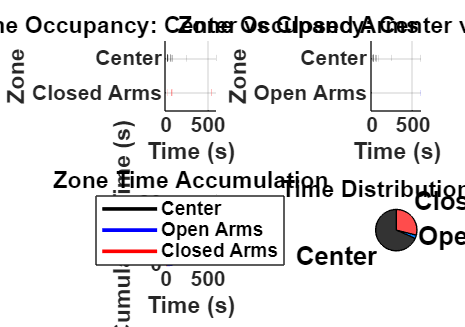

%% 9. Visualization
t = (0:nFrames-1) * dt;

% Figure 1: Zone occupancy over time
fig1 = figure('Name','EPM Zone Occupancy','NumberTitle','off', 'Position', [100 100 1200 900]);

% Zone occupancy plot - Center vs Closed Arms (Efficient version)
subplot(2,2,1);
hold on;

% Find transitions and plot segments instead of individual frames
% This is much more efficient for long recordings

% For center zone
center_starts = find(diff([0; in_center]) == 1);
center_ends = find(diff([in_center; 0]) == -1);

for i = 1:length(center_starts)
    start_time = t(center_starts(i));
    end_time = t(center_ends(i));
    plot([start_time end_time], [2 2], 'k', 'LineWidth', 4);
end

% For closed arms
closed_starts = find(diff([0; in_closed_arms]) == 1);
closed_ends = find(diff([in_closed_arms; 0]) == -1);

for i = 1:length(closed_starts)
    start_time = t(closed_starts(i));
    end_time = t(closed_ends(i));
    plot([start_time end_time], [1 1], 'r', 'LineWidth', 4);
end

xlabel('Time (s)');
ylabel('Zone');
title('Zone Occupancy: Center vs Closed Arms');
ylim([0.5 2.5]);
yticks([1, 2]);
yticklabels({'Closed Arms', 'Center'});
xlim([0 total_time_s]); % Show entire time course
grid on;

% Zone occupancy plot - Center vs Open Arm (Efficient version)
subplot(2,2,2);
hold on;

% For center zone (reuse from above or recalculate)
for i = 1:length(center_starts)
    start_time = t(center_starts(i));
    end_time = t(center_ends(i));
    plot([start_time end_time], [2 2], 'k', 'LineWidth', 4);
end

% For open arms
open_starts = find(diff([0; in_open_arms]) == 1);
open_ends = find(diff([in_open_arms; 0]) == -1);

for i = 1:length(open_starts)
    start_time = t(open_starts(i));
    end_time = t(open_ends(i));
    plot([start_time end_time], [1 1], 'b', 'LineWidth', 4);
end

xlabel('Time (s)');
ylabel('Zone');
title('Zone Occupancy: Center vs Open Arms');
ylim([0.5 2.5]);
yticks([1, 2]);
yticklabels({'Open Arms', 'Center'});
xlim([0 total_time_s]); % Show entire time course
grid on;

% Cumulative time in zones
subplot(2,2,3);
stairs(t, cumsum(in_center)*dt, 'k-', 'LineWidth', 2); hold on;
stairs(t, cumsum(in_open_arms)*dt, 'b-', 'LineWidth', 2);
stairs(t, cumsum(in_closed_arms)*dt, 'r-', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Cumulative Time (s)');
title('Zone Time Accumulation');
legend('Center', 'Open Arms', 'Closed Arms', 'Location', 'best');
grid on;
xlim([0 total_time_s]); % Show entire time course

% Zone pie chart
subplot(2,2,4);
zone_labels = {'Center', 'Open Arms', 'Closed Arms'};
zone_times = [time_in_center_s, time_in_open_arms_s, time_in_closed_arms_s];
pie(zone_times, zone_labels);
title('Time Distribution (%)');
colormap([0.2 0.2 0.2; 0 0.5 1; 1 0.3 0.3]);

% Figure 2: Detailed analysis
fig2 = figure('Name','EPM Detailed Analysis','NumberTitle','off', 'Position', [100 100 1200 800]);

% Trajectory plot
subplot(2,3,1);
plot(C(:,1), C(:,2), 'k-', 'LineWidth', 1, 'DisplayName', 'Animal Path'); hold on;

% Plot EPM zones with labels
patch(center_zone.x, center_zone.y, [0.8 0.8 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'k', 'LineWidth', 2);
text(center_x, center_y, 'Center', 'HorizontalAlignment', 'center', 'FontWeight', 'bold');

patch(open_arm1.x, open_arm1.y, [0.7 0.7 1], 'FaceAlpha', 0.2, 'EdgeColor', 'b', 'LineWidth', 2);
text(center_x, center_y - arm_length_px/2, 'Open Arm 1', 'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'Color', 'b');

patch(open_arm2.x, open_arm2.y, [0.7 0.7 1], 'FaceAlpha', 0.2, 'EdgeColor', 'b', 'LineWidth', 2);
text(center_x, center_y + arm_length_px/2, 'Open Arm 2', 'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'Color', 'b');

patch(closed_arm1.x, closed_arm1.y, [1 0.7 0.7], 'FaceAlpha', 0.2, 'EdgeColor', 'r', 'LineWidth', 2);
text(center_x + arm_length_px/2, center_y, 'Closed Arm 1', 'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'Color', 'r');

patch(closed_arm2.x, closed_arm2.y, [1 0.7 0.7], 'FaceAlpha', 0.2, 'EdgeColor', 'r', 'LineWidth', 2);
text(center_x - arm_length_px/2, center_y, 'Closed Arm 2', 'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'Color', 'r');

xlim([min_x, max_x]);
ylim([min_y, max_y]);
xlabel('X (pixels)'); ylabel('Y (pixels)');
title('EPM Trajectory with Zone Labels');
axis equal; grid on;

% Individual arm time breakdown
subplot(2,3,2);
arm_times = [time_in_open1_s, time_in_open2_s, time_in_closed1_s, time_in_closed2_s];
bar(arm_times);
set(gca, 'XTickLabel', {'Open1', 'Open2', 'Closed1', 'Closed2'});
ylabel('Time (s)');
title('Time in Individual Arms');
grid on;

% Individual arm entries
subplot(2,3,3);
arm_entries = [entries_open1, entries_open2, entries_closed1, entries_closed2];
bar(arm_entries);
set(gca, 'XTickLabel', {'Open1', 'Open2', 'Closed1', 'Closed2'});
ylabel('Number of Entries');
title('Entries to Individual Arms');
grid on;

% Speed in different zones
% Speed in different zones - CORRECTED VERSION
subplot(2,3,4);

% Check if each zone has data
has_center_data = ~isempty(speed_in_center(speed_in_center>0));
has_open_data = ~isempty(speed_in_open(speed_in_open>0));
has_closed_data = ~isempty(speed_in_closed(speed_in_closed>0));

if has_center_data || has_open_data || has_closed_data
    % Create cell array for boxplot data
    box_data_cell = {};
    group_labels = {};
    group_vector = [];
    
    % Add center data if available
    if has_center_data
        center_speeds = speed_in_center(speed_in_center>0);
        box_data_cell{end+1} = center_speeds;
        group_labels{end+1} = 'Center';
        group_vector = [group_vector; ones(length(center_speeds), 1)];
    end
    
    % Add open arm data if available
    if has_open_data
        open_speeds = speed_in_open(speed_in_open>0);
        box_data_cell{end+1} = open_speeds;
        group_labels{end+1} = 'Open';
        group_vector = [group_vector; 2*ones(length(open_speeds), 1)];
    end
    
    % Add closed arm data if available
    if has_closed_data
        closed_speeds = speed_in_closed(speed_in_closed>0);
        box_data_cell{end+1} = closed_speeds;
        group_labels{end+1} = 'Closed';
        group_vector = [group_vector; 3*ones(length(closed_speeds), 1)];
    end
    
    % Combine all data
    if ~isempty(box_data_cell)
        all_speeds = vertcat(box_data_cell{:});
        boxplot(all_speeds, group_vector, 'Labels', group_labels);
        ylabel('Speed (cm/s)');
        title('Speed Distribution by Zone');
        grid on;
    else
        text(0.5, 0.5, 'No speed data in any zone', 'HorizontalAlignment', 'center');
        title('Speed Distribution by Zone');
        axis off;
    end
else
    text(0.5, 0.5, 'No speed data available', 'HorizontalAlignment', 'center');
    title('Speed Distribution by Zone');
    axis off;
end

% Speed over time
subplot(2,3,5);
plot(t, speed_cm_s, 'b-', 'LineWidth', 1);
xlabel('Time (s)'); ylabel('Speed (cm/s)');
title('Speed Profile');
ylim([0 60]); grid on;

% Zone entries comparison
subplot(2,3,6);
bar([entries_center, entries_open, entries_closed]);
set(gca, 'XTickLabel', {'Center', 'Open Arms', 'Closed Arms'});
ylabel('Number of Entries');
title('Zone Entries (Combined)');
grid on;

%% 10. Save results
timestamp = datetime('now', 'Format', 'yyyy-MM-dd_HH-mm-ss');
baseFilename = sprintf('EPM_Results_%s', timestamp);

% Save figures
saveas(fig1, sprintf('%s_zone_occupancy.fig', baseFilename));
saveas(fig1, sprintf('%s_zone_occupancy.png', baseFilename));

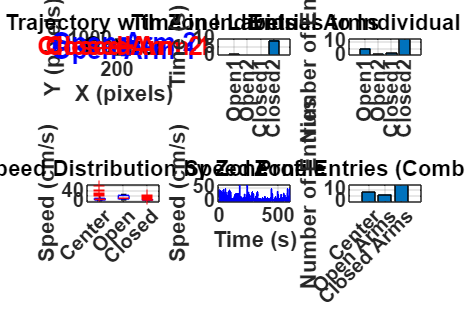

saveas(fig2, sprintf('%s_detailed_analysis.fig', baseFilename));
saveas(fig2, sprintf('%s_detailed_analysis.png', baseFilename));


% Save data to CSV
results_table = table(...
    total_time_s, time_in_center_s, time_in_open_arms_s, time_in_closed_arms_s, ...
    time_in_open1_s, time_in_open2_s, time_in_closed1_s, time_in_closed2_s, ...
    percent_in_center, percent_in_open_arms, percent_in_closed_arms, ...
    entries_center, entries_open, entries_closed, ...
    entries_open1, entries_open2, entries_closed1, entries_closed2, ...
    avg_time_center, avg_time_open, avg_time_closed, ...
    open_arm_preference, open_arm_entry_ratio, ...
    mean(speed_cm_s), mean(speed_in_center, 'omitnan'), mean(speed_in_open, 'omitnan'), mean(speed_in_closed, 'omitnan'), ...
    'VariableNames', {...
    'Total_Time_s', 'Time_Center_s', 'Time_OpenArms_s', 'Time_ClosedArms_s', ...
    'Time_Open1_s', 'Time_Open2_s', 'Time_Closed1_s', 'Time_Closed2_s', ...
    'Percent_Center', 'Percent_OpenArms', 'Percent_ClosedArms', ...
    'Entries_Center', 'Entries_OpenArms', 'Entries_ClosedArms', ...
    'Entries_Open1', 'Entries_Open2', 'Entries_Closed1', 'Entries_Closed2', ...
    'AvgTime_Center_s', 'AvgTime_Open_s', 'AvgTime_Closed_s', ...
    'OpenArm_Preference_percent', 'OpenArm_EntryRatio', ...
    'MeanSpeed_Overall_cm_s', 'MeanSpeed_Center_cm_s', 'MeanSpeed_Open_cm_s', 'MeanSpeed_Closed_cm_s'});

writetable(results_table, sprintf('%s_summary.csv', baseFilename));

% Save detailed data
detailed_data = table(t(:), C(:,1), C(:,2), speed_cm_s(:), ...
    in_center, in_open_arms, in_closed_arms, in_open1, in_open2, in_closed1, in_closed2, ...
    'VariableNames', {'Time_s', 'X_px', 'Y_px', 'Speed_cm_s', ...
    'In_Center', 'In_OpenArms', 'In_ClosedArms', ...
    'In_Open1', 'In_Open2', 'In_Closed1', 'In_Closed2'});

writetable(detailed_data, sprintf('%s_detailed.csv', baseFilename));

% Save to MAT file
save(sprintf('%s_data.mat', baseFilename), 'results_table', 'detailed_data', 'C', 'speed_cm_s', 't');

fprintf('\n========================================\n');

fprintf('Results saved as: %s_*\n', baseFilename);

Results saved as: EPM_Results_2025-12-07_01-00-02_*


fprintf('========================================\n');